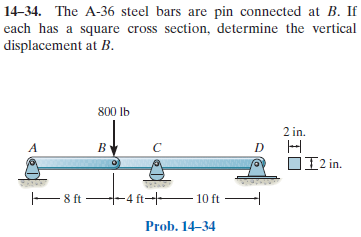

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-34P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-34P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('hinge', 'force', 'Hb', 8*u.ft);
b = b.add('concentrated', 'force', -800*u.lbf, 8*u.ft);
b = b.add('reaction', 'force', 'Rc', 12*u.ft);
b = b.add('reaction', 'force', 'Rd', 22*u.ft);
b.L = 22*u.ft;

# section properties

b.E = rewrite(29e3*u.ksi, [u.lbf u.ft]);
b.I = rewrite(2^4/12*u.in^4, u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{504\,x}{18125} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{9\,\left(x-12\,\mathrm{ft}\right)\,\left(-x^{2}+12\,x\,\mathrm{ft}+80\,{\mathrm{ft}}^{2}\right)}{18125}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }x\in \left(8\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{18\,\left(x-12\,\mathrm{ft}\right)\,\left(x-22\,\mathrm{ft}\right)\,\left(x-32\,\mathrm{ft}\right)}{90625}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{504}{18125} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{9\,\left(3\,x^{2}-48\,x\,\mathrm{ft}+64\,{\mathrm{ft}}^{2}\right)}{18125}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }x\in \left(8\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{18\,\left(3\,x^{2}-132\,x\,\mathrm{ft}+1352\,{\mathrm{ft}}^{2}\right)}{90625}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq 8\,\mathrm{ft}\\ -800\,\left(x-8\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }x\in \left(8\,\mathrm{ft},12\,\mathrm{ft}\right]\\ 320\,\left(x-22\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq 8\,\mathrm{ft}\\ -800\,\mathrm{lbf} & \text{ if }x\in \left(8\,\mathrm{ft},12\,\mathrm{ft}\right]\\ 320\,\mathrm{lbf} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rc} & 1120\,\mathrm{lbf}\\ \mathrm{Rd} & -320\,\mathrm{lbf} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & 800\,\mathrm{lbf} \end{array}\right)$$

# shear and moment diagram

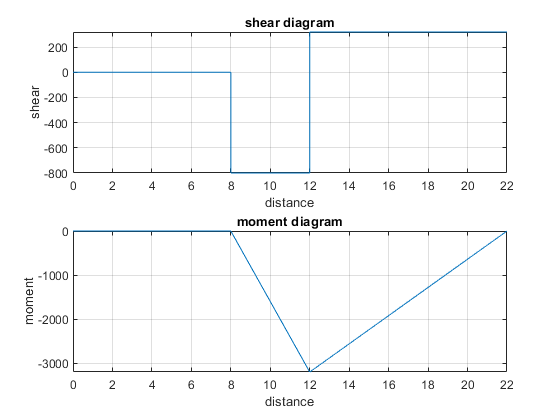

beam.shear_moment(m, v, [0 b.L]);

# dispalcement at B

b.E = rewrite(b.E, u.ksi);
b.I = rewrite(b.I, u.in);
yB = rewrite(y(8*u.ft), u.in);
yB_vpa = vpa(yB, 3) %#ok<NASGU> 

$$yB\_vpa = -2.67\,\mathrm{in}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear yB_vpa;